# Basic Radar Design: Exercise 4 - Simulation & Detection 

In Exercise 4 we will use the results of Exercises 1, 2 and 3 , to set-up Simulation & Detection

Set up Linear FM Waveform (Done in Exercise 1)

Radar Antenna Array (Done in Exercise 2)

Complete the missing parameters in:

- Transmitter, Receiver, and radarTranceiver System Object (All done)

-         Gain, and Peak Power

- Target, Scene, and Environment. 

-         Position, Velocity and RCS

- Signal Processing: Target Detection

-         Noise Floor , and Detection Threshold

Run and observe 

- Noise Floor of Plot as compared to calculated Noise Floor

- Level of Detected signal at 90 km to the specified Pd and Pf

## Radar Configuration

Must detect a target of RCS = 0.1 msq between 2 km and 100 km, 

clear
clc

fc     = 2e9;                   % Operating Frequency
c = physconst('LightSpeed');    % Propagation speed (m/s)
Lam = c/fc;                     % Radar wavelength (m)
R_max = 100e3;                  % Maximum range (m) = 100 km

% Detection Parameters
pd      = 0.9;                  % Probability of detection
pfa     = 1e-6;                 % Probability of false alarm
minRCS  = 0.1;                  % Target RCS = 0.1 sq meter


## Set up Linear FM Waveform (Done in Exercise 1)

Waveform = phased.LinearFMWaveform('SampleRate',1.5e+06,...
        'PulseWidth',6.6667e-05,'PRF',1500,'SweepBandwidth',1e+06, ...
        'SweepDirection','Up','SweepInterval','Positive', ...
        'Envelope','Rectangular','NumPulses',1,'FrequencyOffset',0);
Fs = Waveform.SampleRate;

% The below code is to extract parameters from the Waveform
BW     = Waveform.SweepBandwidth ;      % 1 MHz
prf    = Waveform.PRF ;                 % 1.5 kHz
PW = Waveform.PulseWidth ;              % PW = 66.67 microSec 
R_res = bw2rangeres(BW,c) ;             % R_res = c/(2*BW) = 150 m

% Create a Matched Filter object
coeff = getMatchedFilter(Waveform);

% Compute the Match Filter Gain to be used later
MF_Gain = matchinggain(PW,BW);

## Radar Antenna Array (Done in Exercise 2)

Array = phased.URA('Size',[10 10],...
                'Lattice','Rectangular','ArrayNormal','x');
% The multiplication factor for lambda units to meter conversion
Array.ElementSpacing = [0.5 0.5]*0.15; % 0.15 m is Lambda/2 at 2GHz
    % Calculate Row taper
    rwind = ones(1,10).';
    % Calculate Column taper
    cwind = ones(1,10).';
    % Calculate taper
    taper = rwind*cwind.';
    Array.Taper = taper.';

% Create an isotropic antenna element
Elem = phased.IsotropicAntennaElement;
Elem.BackBaffled = false;
Elem.FrequencyRange = [0 2000000000];
Array.Element = Elem;

% Find Array Gain
Array_Gain = directivity( Array, fc, [0;0] );
BeamW = beamwidth(Array, fc);

## Transmitter, Receiver, and Transceiver

% Fill in the values obtained from Exercise 3 (Radar Designer App)
Npulses = 10;
Tx_Amp_Gain = 10;               % Transmit Amplifier Gain in dB
Rx_Amp_Gain = 10;               % Receive Amplifier Gain in dB
Ppower = 368;                 % Peak Power in Watt from Radar Designer App
              % Ppower can also be found using the function radareqsarpow()

NF = 7;                         % Receiver Noise Figure in dB

% Set up Radiator (to radiate Signal from Array)
Radiator = phased.Radiator('OperatingFrequency',fc, ...
                                'Sensor',Array, 'WeightsInputPort', false);
% Set up Collector (to receive Signal from Array)
Collector = phased.Collector('OperatingFrequency',fc, 'Sensor',Array);

% Transmitter Set-up
Tx = phased.Transmitter('PeakPower',Ppower , 'Gain',Tx_Amp_Gain , ...
                        'InUseOutputPort',false);
% Receiver Set-up                        
Rx = phased.ReceiverPreamp('SampleRate',Fs , 'Gain',Rx_Amp_Gain ,...
                           'NoiseFigure',NF , 'EnableInputPort',false);
% Define Radar function
Radar_IQ = radarTransceiver('Waveform',Waveform , 'Transmitter',Tx ,...
        'TransmitAntenna',Radiator , 'ReceiveAntenna',Collector ,...
        'Receiver',Rx , 'ElectronicScanMode','None' , 'NumRepetitions',1);

## Target, Scene, and Environment

Stationary Radar at the origin and 2 targets: 

- One approaching at 90 km with an RCS of 0.2 msq

- One receeding at 50 km with an RCS of 0.5 msq

- Radar and Targets at the same height (z = 0 m)

Scene = radarScenario( 'UpdateRate',prf , 'StopTime',Npulses/prf );

% Radar
Rdr_Pos = [0 ; 0 ; 0] ;
Rdr_Vel = [0 ; 0 ; 0] ;
Rdr_Plat = platform( Scene, 'Sensors',{Radar_IQ} , 'Position',Rdr_Pos.' ) ;
        Rdr_Plat.Trajectory = kinematicTrajectory('SampleRate',prf ,...
                              'Position',Rdr_Pos , 'Velocity', Rdr_Vel.') ;

% Target 1&2: Positions, Velocities, and RCS 
Tgt_Pos = [89000 50000 ; 0 4000 ; 0 0];
Tgt_Vel = [40 -20 ; 0 20 ; 0 0]; 
Tgt_RCS = [0.3 0.5] ;          
Tgt_RCS_dBsm = pow2db(Tgt_RCS);

% Target 1 Platform
Tgt1_Plat = platform( Scene , 'Position',Tgt_Pos(:,1)' ) ;
        Tgt1_Plat.Trajectory = kinematicTrajectory('SampleRate',prf ,...
                    'Position',Tgt_Pos(:,1)' , 'Velocity',Tgt_Vel(:,1)') ;
        Tgt1_Plat.Signatures = { rcsSignature('Pattern' , Tgt_RCS_dBsm(1)*ones(2,2) ) } ;

% Target #2 Platform
Tgt2_Plat = platform( Scene , 'Position',Tgt_Pos(:,2)' ) ;
        Tgt2_Plat.Trajectory = kinematicTrajectory('SampleRate',prf ,...
                    'Position',Tgt_Pos(:,2)' , 'Velocity',Tgt_Vel(:,2)') ;
        Tgt2_Plat.Signatures = { rcsSignature('Pattern' , Tgt_RCS_dBsm(2)*ones(2,2)) } ;

% Free Space propagation
Channel = phased.FreeSpace('SampleRate',Fs,'TwoWayPropagation',true,...
                            'OperatingFrequency',fc);

## Signal Processing: Receive Signal Simulation

#### Generate Echos

Rx_Pulse = complex( zeros(Fs/prf, Array.Size(1)^2) );
All_Pulses = complex( zeros(Fs/prf, Array.Size(1)^2, Npulses) );
counter = 0 ;
restart(Scene)
while advance(Scene)
    counter = counter + 1;
    Rx_Pulse = receive(Scene);
    All_Pulses(:, :, counter) = Rx_Pulse{1} ; 
end
Rx_Tot = squeeze(sum(All_Pulses,2));     % sum over all antenna elements                

#### Find Detection Threshold

Ideal_Noise_Power = noisepow(BW, NF, 290) ;             
SNR_Th = npwgnthresh(pfa,1,'noncoherent') ;  % SNR for 1 pulse         
NP_dB = pow2db(Ideal_Noise_Power) + MF_Gain + Array_Gain +Rx_Amp_Gain; 
Threshold_dB = SNR_Th + NP_dB   ;  

#### Range Doppler Processing

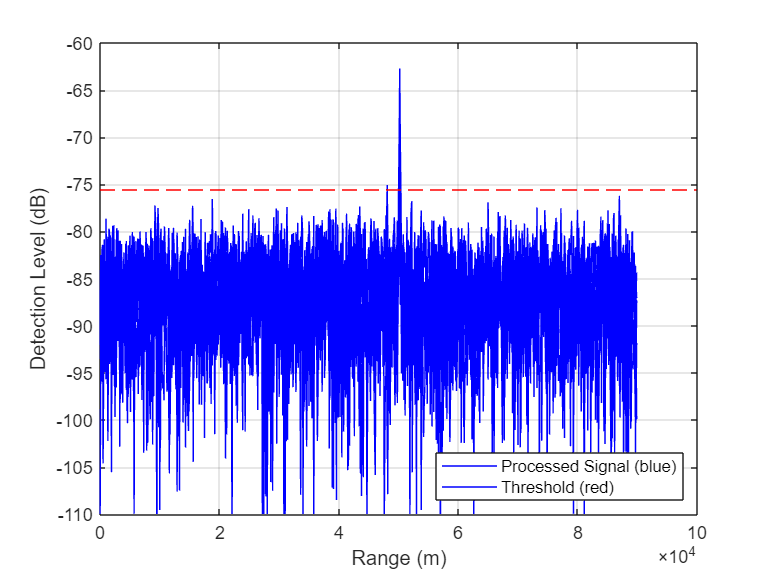

RngDop = phased.RangeDopplerResponse('RangeMethod','Matched filter', ...
            'DopplerOutput','Speed', 'PropagationSpeed',c, ...
            'OperatingFrequency',fc, 'SampleRate',Fs);

[Resp, RngGrid, DopGrid] = RngDop( Rx_Tot , coeff ) ;

% set plotting limits
Resp_dB = mag2db(abs(Resp)) ;
max_y = max(Threshold_dB , ceil(max(max(Resp_dB))/5)*5)  ; 
min_y = max_y-50 ;

counter = 0;
for n = 1:Npulses
    if max(Resp_dB(:,n)) > Threshold_dB
        counter = counter +1 ;
        [Tgt_Pk,Tgt_Ind] = findpeaks(Resp_dB(:,n), 'MinPeakHeight',Threshold_dB,...
                                 'Sortstr','Descend','MinPeakDistance',10);
    Resp_Sig(:,counter) = Resp_dB(:,n) ;
    end
end

% Plot Detection vs Range 
   figure
    plot(RngGrid,Resp_Sig(:,1:counter),'b' , ...
         [RngGrid(1) RngGrid(end)], [Threshold_dB Threshold_dB],'--r')
         ylim( [min_y  max_y] )  ,  grid 
    legend('Processed Signal (blue)' , 'Threshold (red)' , 'Location','southeast')
    xlabel('Range (m)') , ylabel('Detection Level (dB)')